Ryan Fahrenkrug

MECH 105

Homework 12

10/4/2017

clc
clear
close all


Initialize variables with values

W = 670000; % Jets weight [N]
A=150; % Wing planform area [m^2]
AR=6.5; % Aspect ratio
CD0=0.018; % Drag coefficient at zero lift
p=0.413; % Air density [kg/m^3]
FDv=zeros(100,1); % Creates vector of 100 zeros

Creates  function based on FD/v.

Finds the min of the fuction over the interval [100,1000] (The optimal v).

func = @(v) FDoverv(v,W,CD0,p,A,AR);
opt=fminbnd(func,100,1000); % Optimal steady cruze velocity [m/s]
fprintf('The optimal steady cruze velocity is %3.1f m/s\n',opt)

The optimal steady cruze velocity is 248.6 m/s


Plot of FD/v vs v Showing the Optimal v

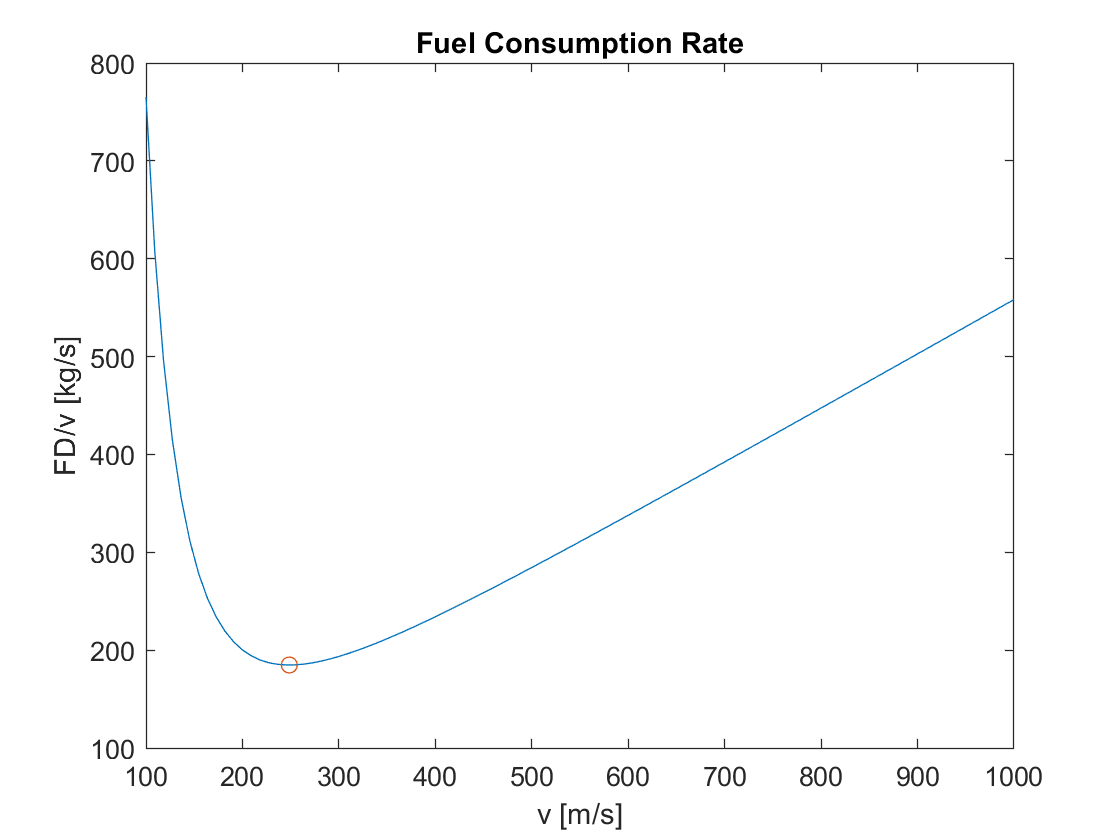

vec=linspace(100,1000); % creates vector of 100-1000
% Fills vec with FDv evaluated from 100 to 1000
for n=1:100
    FDv(n)=FDoverv(vec(n),W,CD0,p,A,AR);
end
% Creates the plot
plot(vec,FDv)
hold on
title('Fuel Consumption Rate')
xlabel('v [m/s]')
ylabel('FD/v [kg/s]')
% Puts a circle over the optimization location
plot(opt,FDoverv(opt,W,CD0,p,A,AR),'o')

 Function being evaluated

function [FDv] = FDoverv(v,W,CD0,p,A,AR)
CL = (2*W)/(p*v^2*A);
CD = CD0+(CL^2)/(pi*AR);
FD = W*CD/CL;
FDv =FD/v;
end
